*Let's clean our Workspace, close any figures and clear the Command Window*

clear; close all; clc;

*Let's load the output of Tutorial 3 and get a look to the data. *

I.e., Source-waveforms reconstruction of the visual evoked potentials - VEP - of one subject performing the following experiment:

four blocks of 150 trials each, for a total of 600 trials, i.e., 300 with faces and 300 with scrambled faces. Faces and scrambled faces were randomly interleaved across trials.

See for further details: [https://doi.org/10.1101/2021.03.16.435599](https://doi.org/10.1101/2021.03.16.435599) 

BIDS_folder=fullfile('/','home', 'sinergiasummerschool', 'Data', 'ds003505');
load(fullfile(BIDS_folder,'derivatives','source_modelling','sub-01','eeg','ROI_data.mat'), 'ROI_data');
ROI_data

ROI_data = struct with fields:
         trial: {1×587 cell}
          elec: [1×1 struct]
     trialinfo: [587×1 double]
         label: {72×1 cell}
       fsample: 250
          time: {1×587 cell}
    sampleinfo: [587×2 double]


**ROI_data** is a structure containing 7 fields, among them:

- 587 VEPs (**trial**) [ 72 ROIs x  625 time-points]

- each trial last 2.5 s (since we have 625 time-samples and a sample frequency of **fsample** = 250 Hz )

- as we can check in the cell-array **time** that contains the time vector for each VEP

- The 72 ROIs' labels are reported in **label**

- In **trialinfo**, 0 stands for scrambled faces and 1 for faces

*Let's select the data refered to faces and plot them.*

VEP_faces=[];
face=1;
index=1;

for k=find(ROI_data.trialinfo==face,1,'first'):find(ROI_data.trialinfo==face,1,'last')
    VEP_faces(index,:,:)=ROI_data.trial{k};    
    index=index+1;
end

t=ROI_data.time{k};

figure()

plot(t,squeeze(mean(VEP_faces,1)))
xline(0)

ans =   ConstantLine with properties:

    InterceptAxis: 'x'
            Value: 0
            Color: [0.1500 0.1500 0.1500]
        LineStyle: '-'
        LineWidth: 0.5000
            Label: ''
      DisplayName: ''

  Show all properties


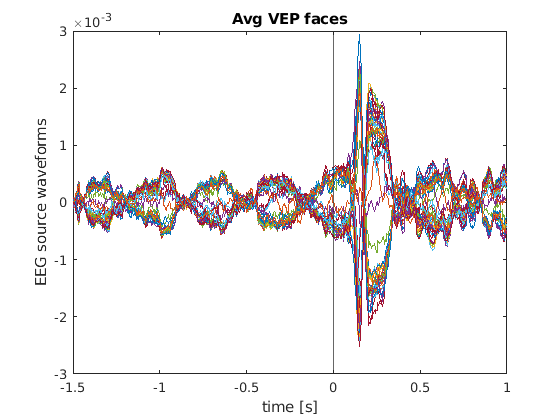

xlabel('time [s]')
ylabel('EEG source waveforms')
title('Avg VEP faces')

*Let's add our toolbox *[https://github.com/PscDavid/dynet_toolbox](https://github.com/PscDavid/dynet_toolbox) *to our path.*

addpath(genpath('dynet_toolbox-master/'))

*Let's started computing the AutoRegressive (AR*) coefficients through the the general linear Kalman filter approach* 

For further details see [https://doi.org/10.1016/j.neuroimage.2009.12.110](https://doi.org/10.1016/j.neuroimage.2009.12.110)

*Remember that an AR process characterizes the current values of a time-series as a weighted linear sum of its previous p values. The Multivariate AutoRegressive (MVAR) models extend the AR approach to multiple time-series. 

p_order=10;
C=0.02;

temp=VEP_faces(1:30,:,324:476);
t_new=t(324:476); % -200 ms +400 ms

gKF=dynet_SSM_KF(temp,p_order,C);

*Let's get a look at gKF*

gKF

gKF = struct with fields:
    AR: [72×72×10×153 double]
     R: [72×72×153 double]
    PY: [30×72×153 double]


We have obtained a structure gKF with the following fields:

- AR [ROIs x ROIs X p X time-samples] --> MVAR model coefficients

- R [ROIs X ROIs X time-samples] --> Measurement Noise Covariance Matrix (W in [https://doi.org/10.1016/j.neuroimage.2009.12.110](https://doi.org/10.1016/j.neuroimage.2009.12.110) )

- PY [Trials X ROIs X time-samples] --> One-step Predictions on Y

We have all the variables we need to compute our connectivity matrix!

*Let's compute the squared Partial Directed Coherence (sPDC)*

f=1:1:30;
sPDC_gKF=dynet_ar2pdc(gKF,ROI_data.fsample,f','sPDC',[],[],0);

*Let's visualize (part of) our connectivity matrix*

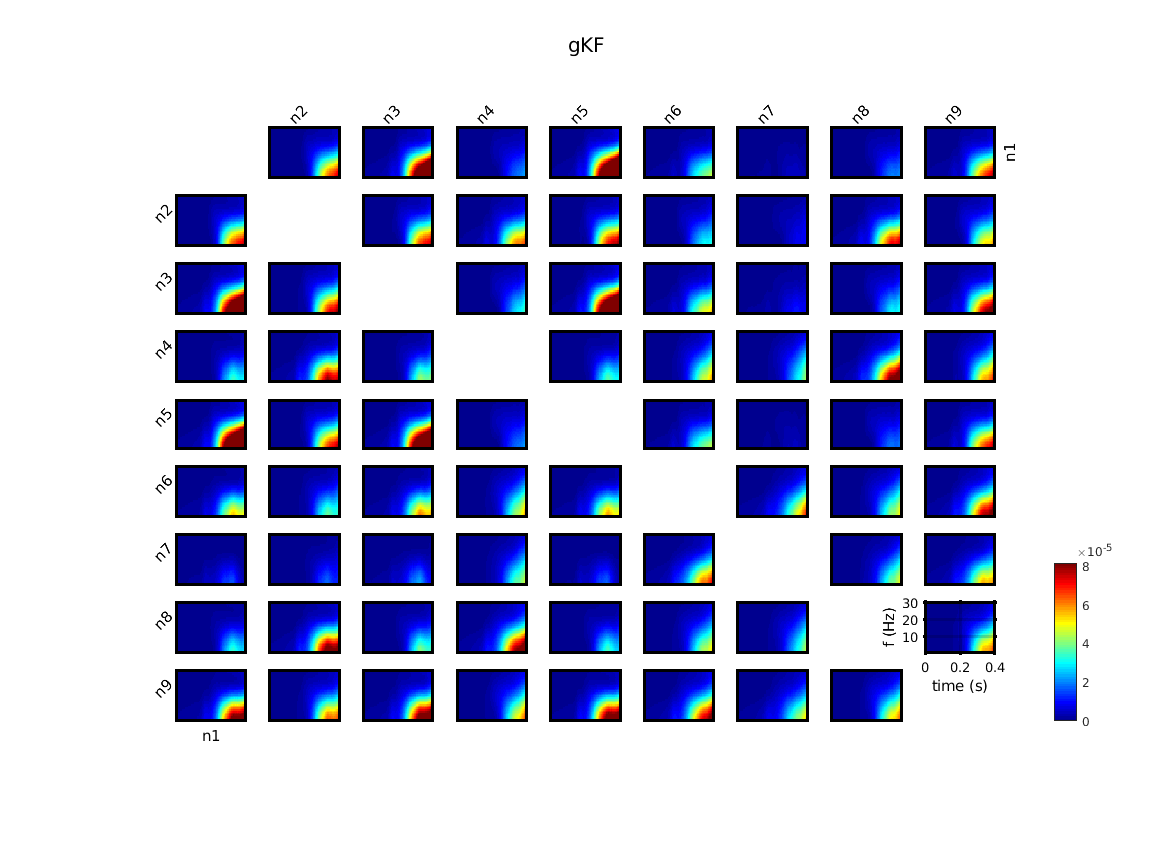

rois=20:28;
dynet_connplot(sPDC_gKF(rois,rois,:,53:end),t_new(53:end),f,[],[],[],0,0) 
sgtitle('gKF')

*Let's compute our connectivity matrix through STOK*

STOK=dynet_SSM_STOK(temp,p_order);

**Q: **In calliing the function, which is the parameter missing compared to the general kalman filter approach? 

**A:** C!

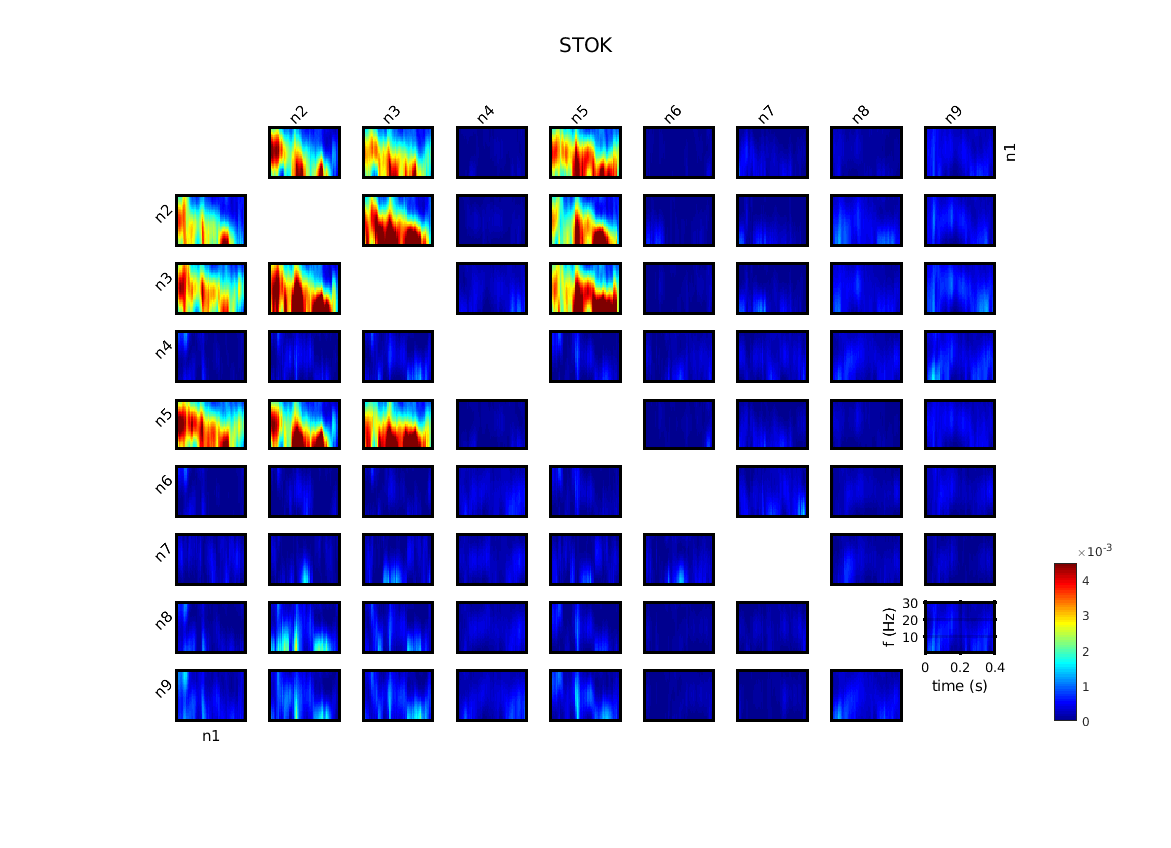

sPDC_SK=dynet_ar2pdc(STOK,ROI_data.fsample,f','sPDC',[],[],1);
dynet_connplot(sPDC_SK(rois,rois,:,53:end),t_new(53:end),f,[],[],[],0,0)
sgtitle('STOK') 

**Q: **What are you observing comparing the figures output of the two different approaches?

**A:** The parameter C that is chosen a priori in the general Kalman filter approach is affecting the results, i.e., the speed of adaptation to the data changes by the filter

In this section we'll include the structural connectivity as prior information and see how it affects the connectivity results.

*First let's take a look at the structural connectivity matrix.*

Note that the structural connectivity matrix contains only 68 ROIs instead of 72. The left and right amygdala (ROIs 35-36 & 71-72) are not included because they are subcortical structures.

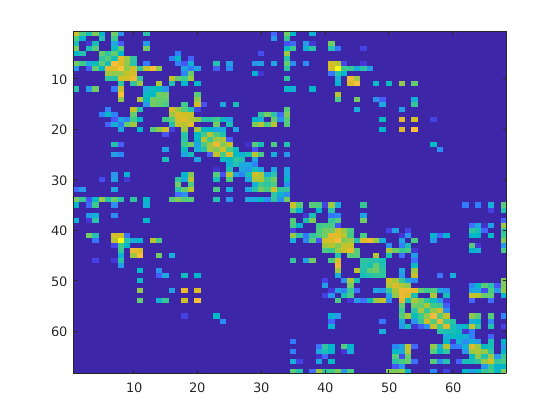

tutorial_folder = fullfile('/','home','sinergiasummerschool','Code','tutorial04-code');
load(fullfile(tutorial_folder, 'SC_prior_siSTOK_sep2021.mat'));
figure
imagesc(SC_prior)

**Q:** What do the values of the structural connectivity matrix represent?

**A: **Each element (x,y) in the matrix contains the number of fibers connecting ROIx and ROIy. The values are normalized between 0 and 1.

*Now let's re-compute the TVAR model, now with the structural priors included.*

sitemp = temp;
sitemp(:,[35,36,71,72],:) = [];
siSTOK = dynet_SSM_siSTOK(sitemp,p_order,SC_prior,.99)

siSTOK = struct with fields:
    AR: [68×68×10×153 double]
     R: [68×68×153 double]
    PY: [30×68×153 double]
     c: [153×1 double]


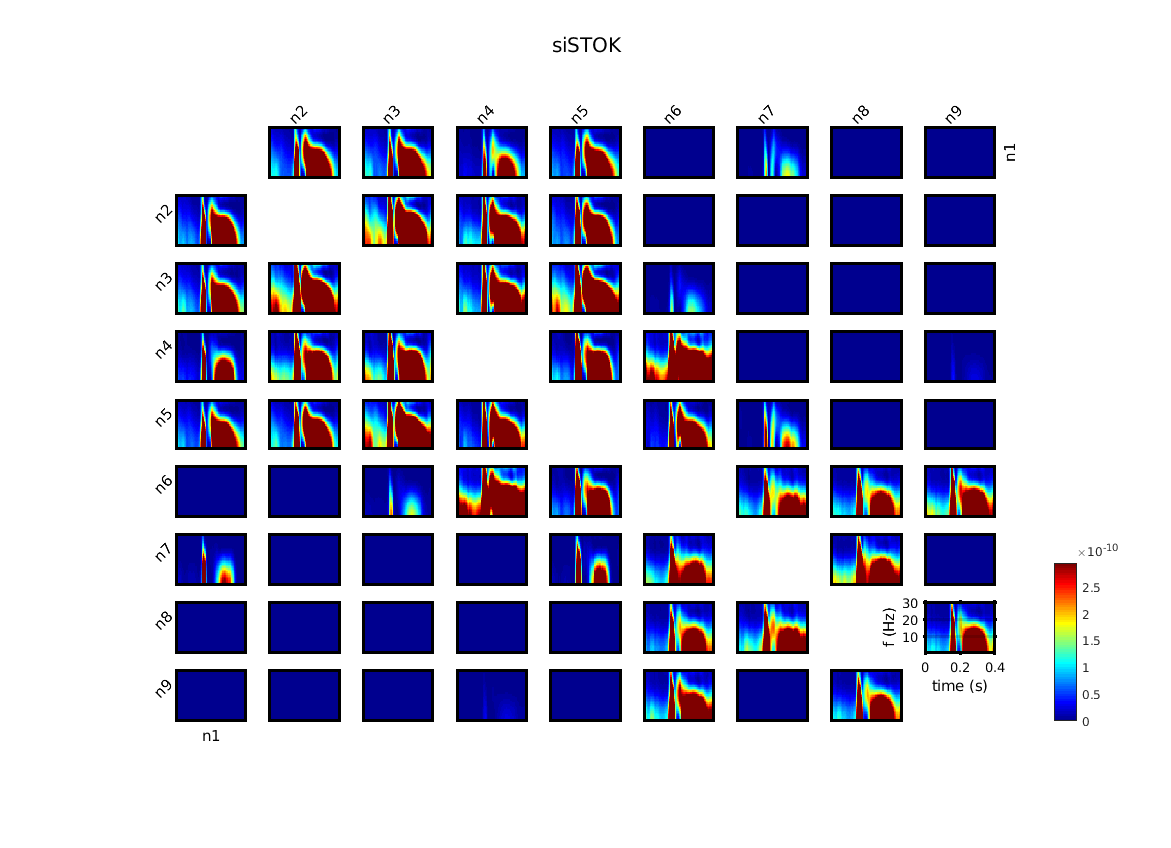

siSTOKtemp.AR=siSTOK.AR(:,:,:,53:end);
siSTOKtemp.R=siSTOK.R(:,:,53:end);
siSTOKtemp.PY=siSTOK.PY(:,:,53:end);
siSTOKtemp.c=siSTOK.c(53:end);

sPDC_siSK=dynet_ar2pdc(siSTOKtemp,ROI_data.fsample,f','sPDC',[],[],1);
dynet_connplot(sPDC_siSK(rois,rois,:,:),t_new(53:end),f,[],[0 0.78],[],0,0)
sgtitle('siSTOK')

*Let's have a look to the structural matrix limited to the ROIs we visualized*

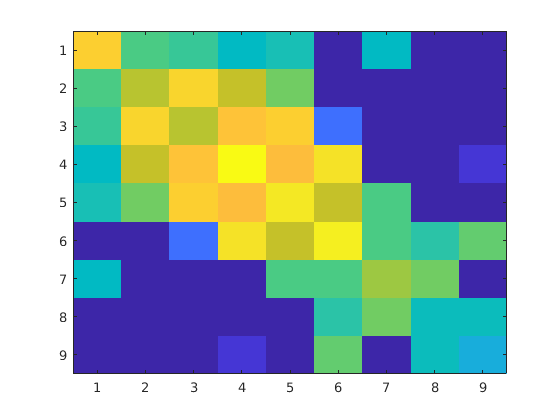

figure()
imagesc(SC_prior(rois,rois))